# **FIT EMPIRICAL BETA PARAMETERS: **$\beta_{fix.emp}$ (from each point of the WRC)

 $\beta_{fix.emp}$ will be calculated from the values $\beta_i$ calculated on each point of the WRC on each sample (included in the output table DATA_FIT_I_DG*_ACAP). 

The empirical expression of $\beta_{fix.emp.Dp}(D_p)$  will depend on$\log D_{10}$, $\log D_{50}$, $\log D_{80}$, porosity (NPOR) and coefficient of uniformity $\log CU$.

## **Option Dg0=1: Empirical expression for **$\beta_{fix.emp,Dp}(Dp)$**for **$D_{g0}=D_{50}/1mm$

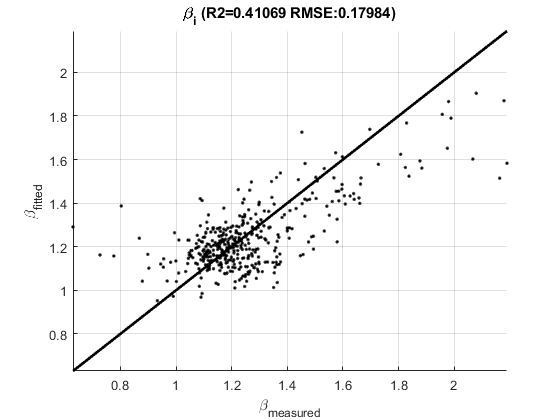

beta_fix.emp =+1.287987+0.513320.*LOGD10-0.506320.*LOGD50-0.033267.*LOGD80+0.564173.*LOGCU-0.325973.*NPOR-0.004290.*LOGD10:LOGD80


% Comment: Data input DATA_INPUT must be present and then the tables with results need to be generated or loaded with scripts: 
% load('DATA_ACAP.mat', 'DATA_INPUT');
% script_ACAP_Get_Results_Tables;
% script_AP81_Get_Result_Tables
% script_AP99_Get_Result_Tables
% script_AP08_Get_Result_Tables;
% script_CNEAP_Get_Result_Tables
%
% Or load data and results from DATA_ACAP.mat:
load('DATA_ACAP.mat');
DATA_I = DATA_FIT_I_DG1_ACAP(DATA_FIT_I_DG1_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGD10+LOGD50+LOGD80+LOGCU+NPOR+LOGD10:LOGD80','beta_fix.emp'));

## **Option Dg0=2: Empirical expression for **$\beta_{fix.emp,Dp}(Dp)$**for **$D_{g0}=D_{50}/0.075mm$:

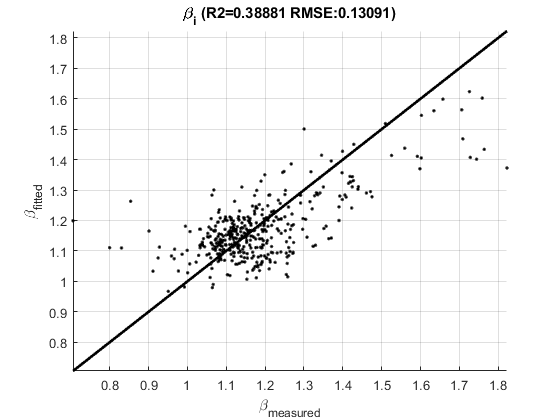

beta_fix.emp =+1.239192+0.340354.*LOGD10-0.335174.*LOGD50-0.019311.*LOGD80+0.375547.*LOGCU-0.220306.*NPOR-0.002935.*LOGD10:LOGD80


DATA_I = DATA_FIT_I_DG2_ACAP(DATA_FIT_I_DG2_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGD10+LOGD50+LOGD80+LOGCU+NPOR+LOGD10:LOGD80','beta_fix.emp'));

## **Option Dg0=3: Empirical expression for **$\beta_{fix.emp,Dp}(Dp)$**for **$D_{g0}=D_{50}/0.002mm$:

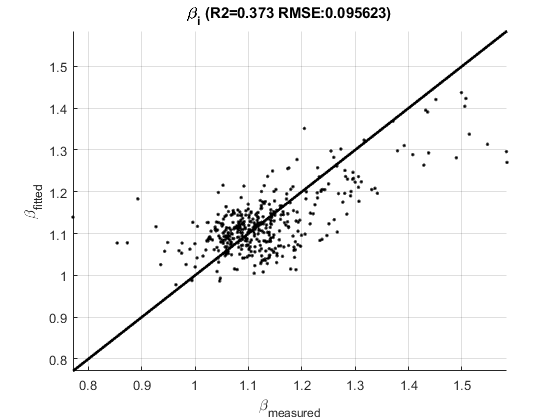

beta_fix.emp =+1.189132+0.232807.*LOGD10-0.228772.*LOGD50-0.011646.*LOGD80+0.257375.*LOGCU-0.151684.*NPOR-0.002031.*LOGD10:LOGD80


DATA_I = DATA_FIT_I_DG3_ACAP(DATA_FIT_I_DG3_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGD10+LOGD50+LOGD80+LOGCU+NPOR+LOGD10:LOGD80','beta_fix.emp'));

## **Option Dg0=4: Empirical expression for **$\beta_{fix.emp,Dp}(Dp)$**for **$$D_{g0}=\sqrt[3]{2650}$$:

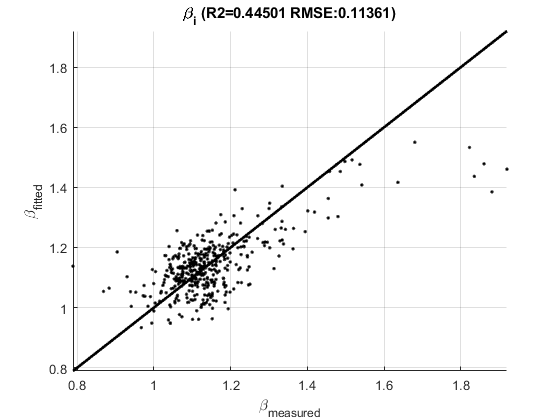

beta_fix.emp =+1.537278+0.271187.*LOGD10-0.246088.*LOGD50+0.017847.*LOGD80+0.288340.*LOGCU-0.136281.*NPOR-0.000910.*LOGD10:LOGD80


DATA_I = DATA_FIT_I_DG4_ACAP(DATA_FIT_I_DG4_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGD10+LOGD50+LOGD80+LOGCU+NPOR+LOGD10:LOGD80','beta_fix.emp'));

## **Option Dg0=5: Empirical expression for **$\beta_{fix.emp,Dp}(Dp)$**for **$$D_{g0}=1$$:

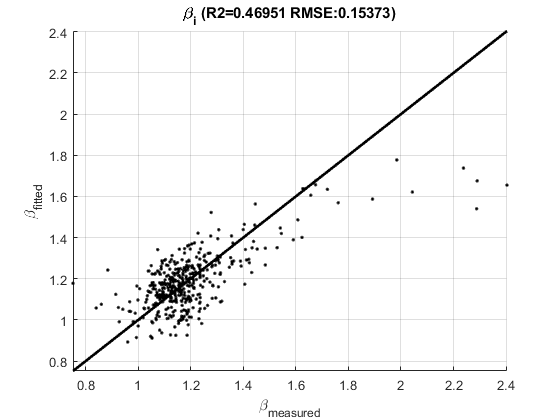

beta_fix.emp =+1.854601+0.378810.*LOGD10-0.333862.*LOGD50+0.036696.*LOGD80+0.395870.*LOGCU-0.161140.*NPOR-0.000472.*LOGD10:LOGD80


DATA_I = DATA_FIT_I_DG5_ACAP(DATA_FIT_I_DG5_ACAP.INTO_BOUND==1,:);
disp(func_ACAP_fit_beta_Dp(DATA_I,'BETAI ~ LOGD10+LOGD50+LOGD80+LOGCU+NPOR+LOGD10:LOGD80','beta_fix.emp'));

clear('DATA_I');